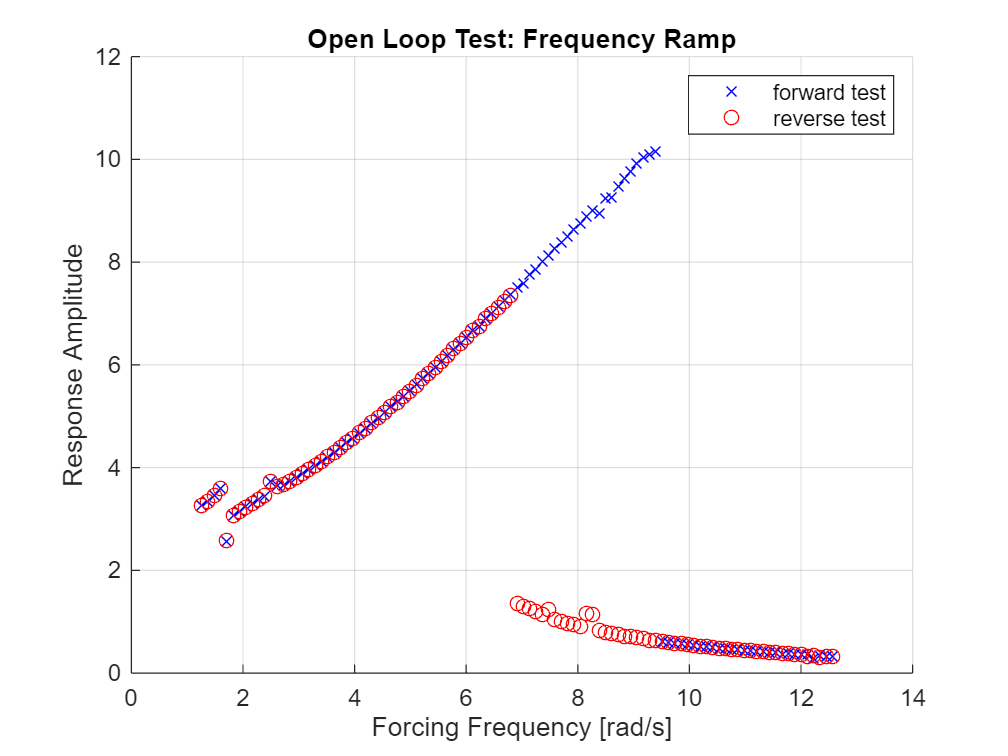

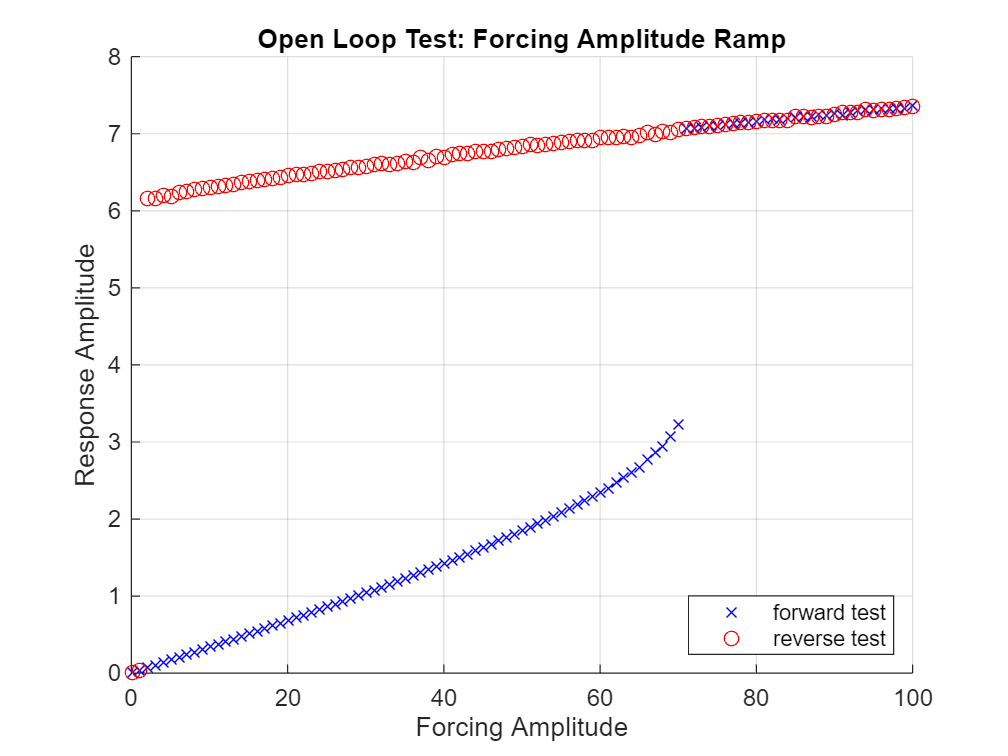

s_curve =    58.7204    2.3145
   62.2062    2.5278
   65.3091    2.7421
   67.7388    2.9565
   69.8280    3.1724
   71.4402    3.3895
   71.7109    3.6053
   71.9256    3.8242
   71.5012    4.0445
   67.2197    4.2545


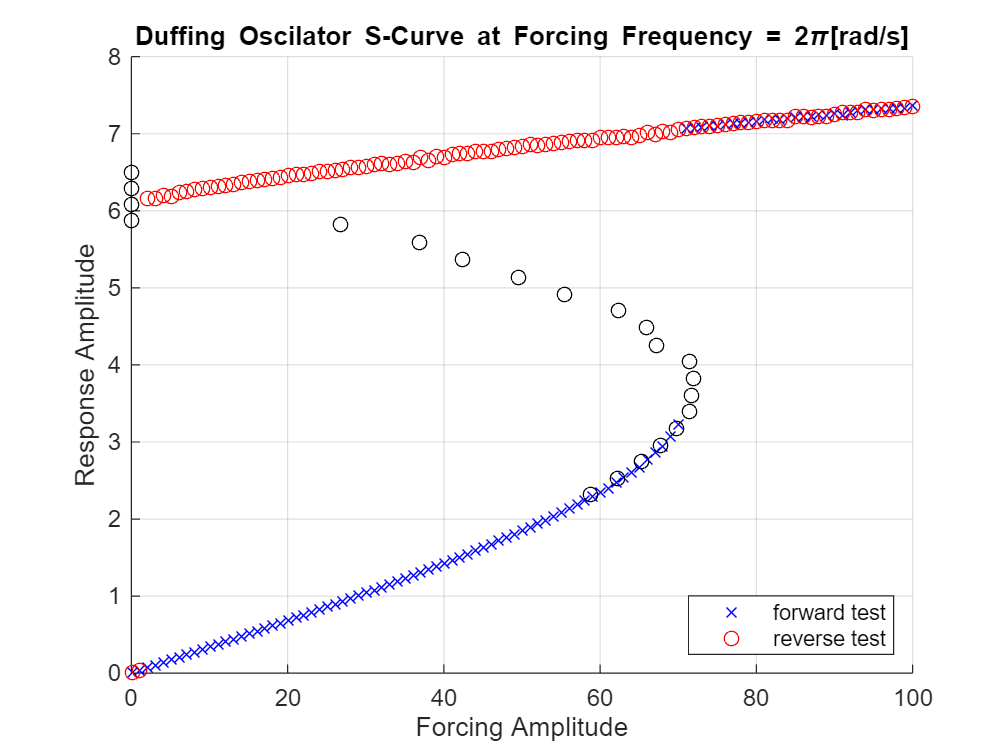

close all;
clear all;
%perform openloop testing first:
openlooptesting

% USEFUL OUTPUT VARIABELS ^^^^
% plot(forcing_vals, response_vals, 'bx');
% plot(forcing_vals2, response_vals2, 'ro');

% Define response ampl range (unstable region)
start_index = 6;       % index of bifurcation acending
end_index = 4;         % index of bifurcation decending (count right to left_

% check if response amplitudes match
response_vals(start_index)

ans = 0.1719

response_vals2(end_index)

ans = 7.3206

response_amp = linspace(response_vals(start_index), response_vals2(end_index) , 11)

response_amp =     0.1719    0.8867    1.6016    2.3165    3.0314    3.7462    4.4611    5.1760    5.8909    6.6057    7.3206


forcing_amp = zeros(size(response_amp));

stabilised.A_vector = [];
stabilised.B_vector = [];

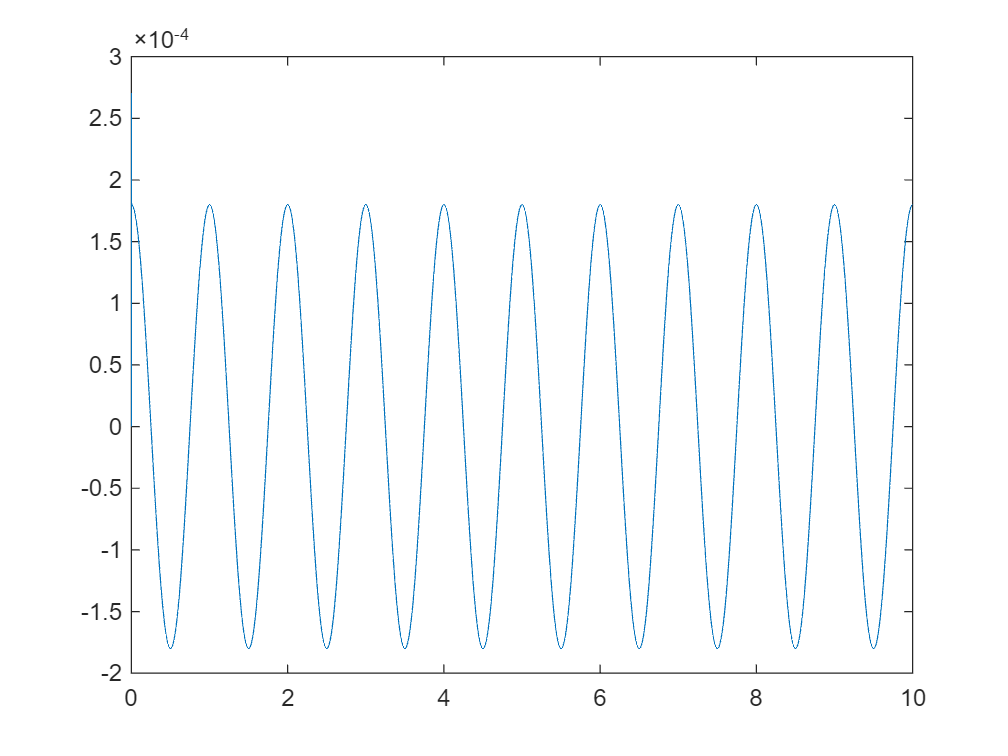

Error using get_last_n_periods (line 10)
Not enough zero crossings detected to extract 10 full periods.

Error in closedloop_test2 (line 57)
        [t_lin2, x_lin2] = get_last_n_periods(trial_out.t_span, trial_out.X_less(:, 1), 10);

Error in 

% define inputs and prepare for CBC
% set initial target
input.A_desired = 0;
input.B_desired = response_amp(1);
control.target_amplitude = response_amp(1);
control.k_num = 7;
control.base_target = zeros(control.k_num, 2); %ref signal
control.base_target(1,:) = [input.A_desired, input.B_desired];
control.coeff_tol = 0.001; %  sum(0.01.*control.base_target(1,:));
control.amp_tol = 0.01; %  sum(0.01.*control.base_target(1,:));


% input.F0 = 1;               % Initial forcing amplitude
% input.w0 = 2 * pi;          % Forcing frequency (rad/s)

for j = (1:length(response_amp))
    reset_model_setup;      % sets basic variables (including controller struct)
    
    outerloop_iteration;
    % already included in outer loop iteration code...
    % [t_lin, x_lin] = get_last_n_periods(trial_out.t_span, input_out.f_history, 20);
    % [A_vec,B_vec] = get_fft_components(t_lin, x_lin, input_out.w0, 7);

    stabilised.A_vector = [stabilised.A_vector, A_vec];
    stabilised.B_vector = [stabilised.B_vector, B_vec];
    

    forcing_amp(j) = sqrt(sum([A_vec,B_vec].^2, "all"));

    % update targets/refs
    if(j+1 > length(response_amp))
        break
    end
    new_ref = [0, response_amp(j+1)];
    old_ref = [experiment.A_target(1, end), experiment.B_target(1, end)];

    temp = old_ref == 0;
    ratio_ref = new_ref./old_ref;
    ratio_ref(temp) = 0;

    
    new_ref_vector = [experiment.A_target(:, end), experiment.B_target(:, end)].*ratio_ref;
    % break
    control.base_target = new_ref_vector;
    j
end

% input.w0

figure;
plot(forcing_amp, response_amp, "-o");
xlabel("Forcing amplitude");
ylabel("Response amplitude");
stabilised.A_vector
stabilised.B_vector

figure;
hold on;
plot(forcing_vals, response_vals, 'bx');
plot(forcing_vals2, response_vals2, 'ro');
plot(forcing_amp, response_amp, 'ko')

xlabel("Forcing Amplitude");
ylabel("Response Amplitude");
title("S-curve at \omega_o = 2\pi");
legend(["acending branch", "decending branch", "controlled unstable branch"], Location="best")
